CurrentData = load('CurrentBuildingVariables.mat');

CurrentData.HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
CurrentData.HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];

CurrentHourlyHeating = CurrentData.HourlyHeatingLoad;
CurrentHourlyCooling = CurrentData.HourlyCoolingLoad;

NewData = load('NewBuildingVariables.mat');

NewData.HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
NewData.HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];

NewHourlyHeating = NewData.HourlyHeatingLoad;
NewHourlyCooling = NewData.HourlyCoolingLoad;

NumberOfBoreholes = 63;
DepthOfBoreholes = 100;
ExtractionRate = 0.030;
PeakLoadCapacity = ExtractionRate*DepthOfBoreholes*NumberOfBoreholes;

Baseline modelling

OldDailyHeatingPeaks = max(CurrentHourlyHeating, [], 1);
OldDailyCoolingPeaks = max(CurrentHourlyCooling, [], 1);
NewDailyHeatingPeaks = max(NewHourlyHeating, [], 1);
NewDailyCoolingPeaks = max(NewHourlyCooling, [], 1);
DaysInMonths = [31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31];
MonthBoundaries = [0, cumsum(DaysInMonths)];  % 0-based for easy indexing

MonthlyPeaks = cell(4, 12);
% Step 4: Extract daily peaks for each month
for month = 1:12
    StartDay = MonthBoundaries(month) + 1;
    EndDay = MonthBoundaries(month + 1);
    MonthlyPeaks{1,month} = table2array(OldDailyHeatingPeaks(1,StartDay:EndDay));
    MonthlyPeaks{2,month} = table2array(OldDailyCoolingPeaks(1,StartDay:EndDay));
    MonthlyPeaks{3,month} = table2array(NewDailyHeatingPeaks(1,StartDay:EndDay));
    MonthlyPeaks{4,month} = table2array(NewDailyCoolingPeaks(1,StartDay:EndDay));
end

colours = [[0 0.4470 0.7410],
    [0.8500 0.3250 0.0980],
    [0.9290 0.6940 0.1250],
    [0.4940 0.1840 0.5560],
    [0.4660 0.6740 0.1880],
    [0.3010 0.7450 0.9330],
    [0.6350 0.0780 0.1840]];


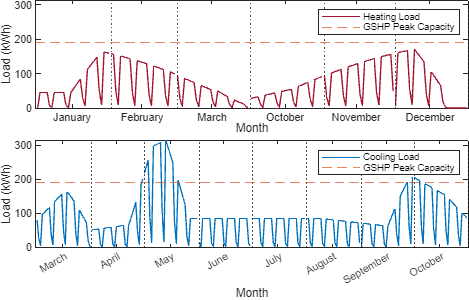

MonthNames = ["January", "February", "March", "April", "May", "June", "July", "August", "September", "October", "November", "December"];

HeatingMonths = [1,2,3,10,11,12];
CoolingMonths = [3,4,5,6,7,8,9,10];
HeatingIndex = 1;
CoolingIndex = 1;

figure('Position',[0 0 500 320]);
tiledlayout(2,1, 'Padding', 'none', 'TileSpacing', 'compact'); 
nexttile;
hold on
for month = HeatingMonths
    xvals = HeatingIndex:HeatingIndex+DaysInMonths(month)-1;
    HeatingLoads = plot(xvals,MonthlyPeaks{3,month},'Color',colours(7,:));
    HeatingIndex = HeatingIndex + DaysInMonths(month);
    xline(HeatingIndex,'LineStyle',':','Color','k')
end
PeakLoad = yline(PeakLoadCapacity,'linestyle', '--','Color',colours(2,:));
legend([HeatingLoads,PeakLoad],{'Heating Load','GSHP Peak Capacity'});
xlim([0 HeatingIndex])
ylim([0 max(table2array(NewDailyCoolingPeaks),[],'all')])
hold off
ylabel("Load (kWh)")%,FontSize=28);
xlabel("Month")%,FontSize=28);
FirstThreeMonths = (MonthBoundaries(HeatingMonths(1:3)))+DaysInMonths(HeatingMonths(1:3))/2;
SecondThreeMonths = FirstThreeMonths(end)+DaysInMonths(HeatingMonths(4));
SecondThreeMonths = [SecondThreeMonths SecondThreeMonths+DaysInMonths(HeatingMonths(5))];
SecondThreeMonths = [SecondThreeMonths SecondThreeMonths(end)+DaysInMonths(HeatingMonths(6))];

xticks([FirstThreeMonths SecondThreeMonths]); % Monthly ticks
xticklabels(MonthNames(HeatingMonths));

box on

CumuluativeXVals = [];

nexttile;
hold on
for month = CoolingMonths
    xvals = CoolingIndex:CoolingIndex+DaysInMonths(month)-1;
    CoolingLoads = plot(xvals,MonthlyPeaks{4,month},'Color',colours(1,:));
    CoolingIndex = CoolingIndex + DaysInMonths(month);
    xline(CoolingIndex,'LineStyle',':','Color','k')
end
PeakLoad = yline(PeakLoadCapacity,'linestyle','--','Color',colours(2,:));
legend([CoolingLoads,PeakLoad],{'Cooling Load','GSHP Peak Capacity'});
xlim([0 CoolingIndex])
ylim([0 max(table2array(NewDailyCoolingPeaks),[],'all')])
hold off
ylabel("Load (kWh)")%,FontSize=28);
xlabel("Month")%,FontSize=28);

xticks(MonthBoundaries(CoolingMonths)+DaysInMonths(CoolingMonths)/2-sum(DaysInMonths(1:2)));%-sum(DaysInMonths(1:2))); % Monthly ticks
xticklabels(MonthNames(CoolingMonths));

box on
fig = gcf;
exportgraphics(fig,'HeatingCooling.eps','Resolution',300) 

Baseline Modelling

% Assume 'monthly_data' is your 1x12 cell array where each cell contains a matrix

% Create a figure window
figure;

% Define the months to plot
months_to_plot = 3:10;

% Number of subplots needed
num_subplots = length(months_to_plot);


% Iterate over each cell and plot on separate subplots
for i = 1:num_subplots
    month = months_to_plot(i)
    % Create a subplot for the current month
    subplot(3,4,i);  % 3 rows, 4 columns, one plot per month
    
    % Extract the matrix from the current cell
    current_matrix = MonthlyPeaks{month};
    
    % Plot the values (e.g., the values directly or max/mean if applicable)
    plot(1:length(current_matrix), current_matrix, '-', 'DisplayName', 'Daily Demand')
    
    
    % Plot a constant line (e.g., y = constant_value)
    constant_value = peak_load_capacity;  % Replace with your desired constant value
    hold on;  % Hold to add the constant line
    yline(constant_value, '--r', 'DisplayName', 'Capacity')
        
    
    % Add labels and title for each subplot
    title(sprintf('Month %d', month));
    xlabel('Day');
    ylabel('Value');
    
    % Add legend to each subplot
    legend('show');
    
    % Optional: Add grid for better readability
    grid on;
    
    % Release hold for the next plot
    hold off;
end

